# Computational Physics (PHY4602) - Programming Fundamentals

## Overview

Computational physics is the study and implementation of numerical analysis to solve problems in physics for which a quantitative theory already exists. It is a subset of computational science and a vital tool for advancing physics research and applications. Mastering programming for computational physics is important because it enables physicists to create and modify computer simulations, models and algorithms that can handle complex and large-scale problems. Programming also helps physicists to visualize, analyze and communicate their results effectively.

## Computational Physics

Computational physics is a subject that deals with numerical approximations of mathematical models in physics when solving them exactly is not feasible. It uses algorithms and computers to compute approximate solutions and errors. Some importances of computers in physics include:

- Solving problems in physics for which a quantitative theory already exists using **numerical analysis.**

- **Analyzing and visualizing data** from experiments and observations to communicate results and findings to other physicists and researchers.

- Running **experiments and monitoring equipment** using computer-controlled instrumentation.

- **Simulating physical phenomena** that are difficult or impossible to observe directly.

- Processing large amounts of data, applying mathematical algorithms and learning from data patterns for **model development**.

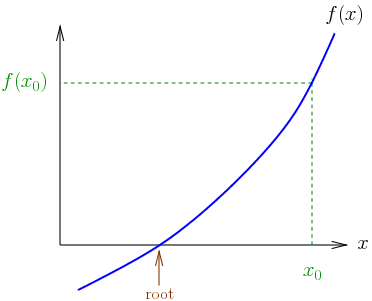

Newton-Rhapson's method for finding roots 

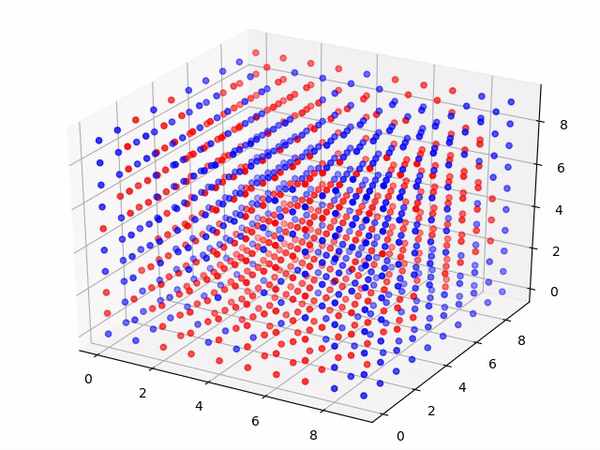

The Ising model simulation of magnetic materials

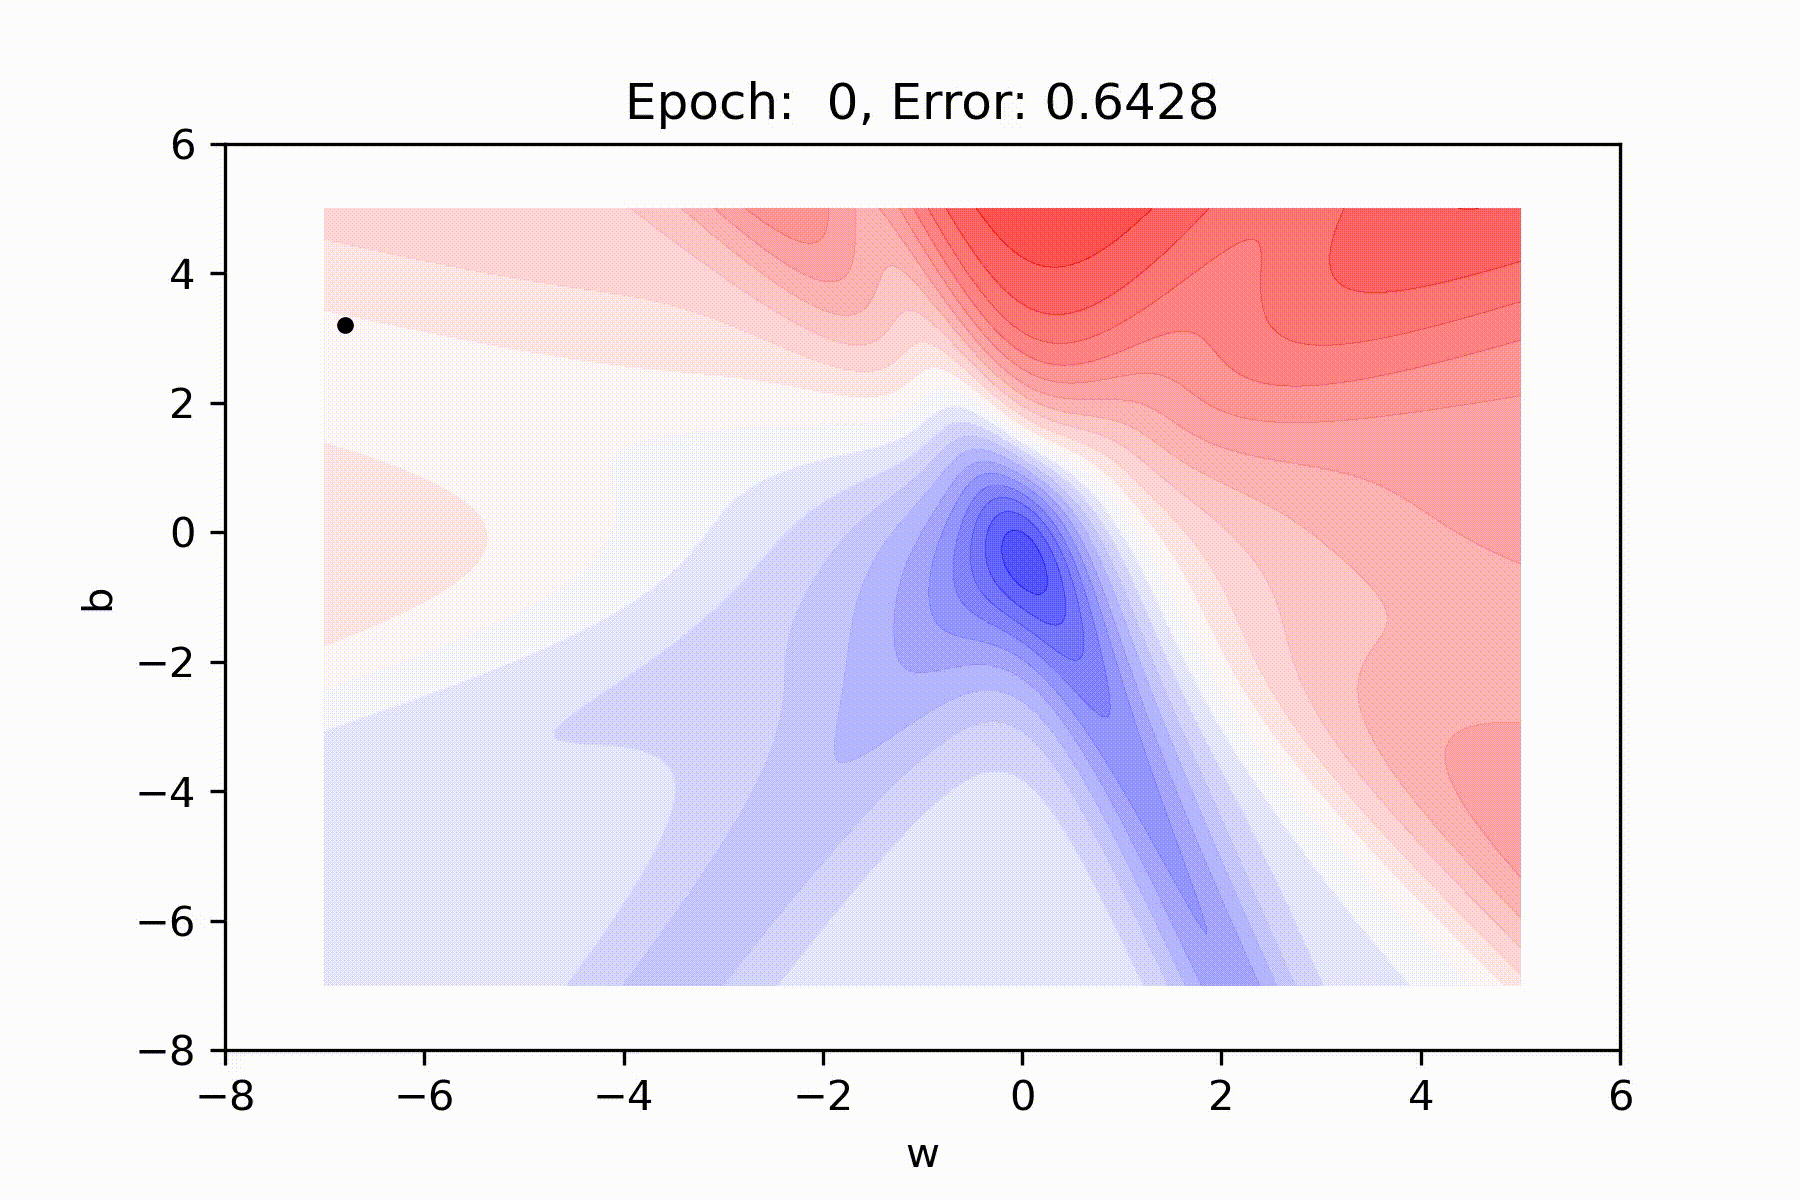

Machine learning application for optimization problems 

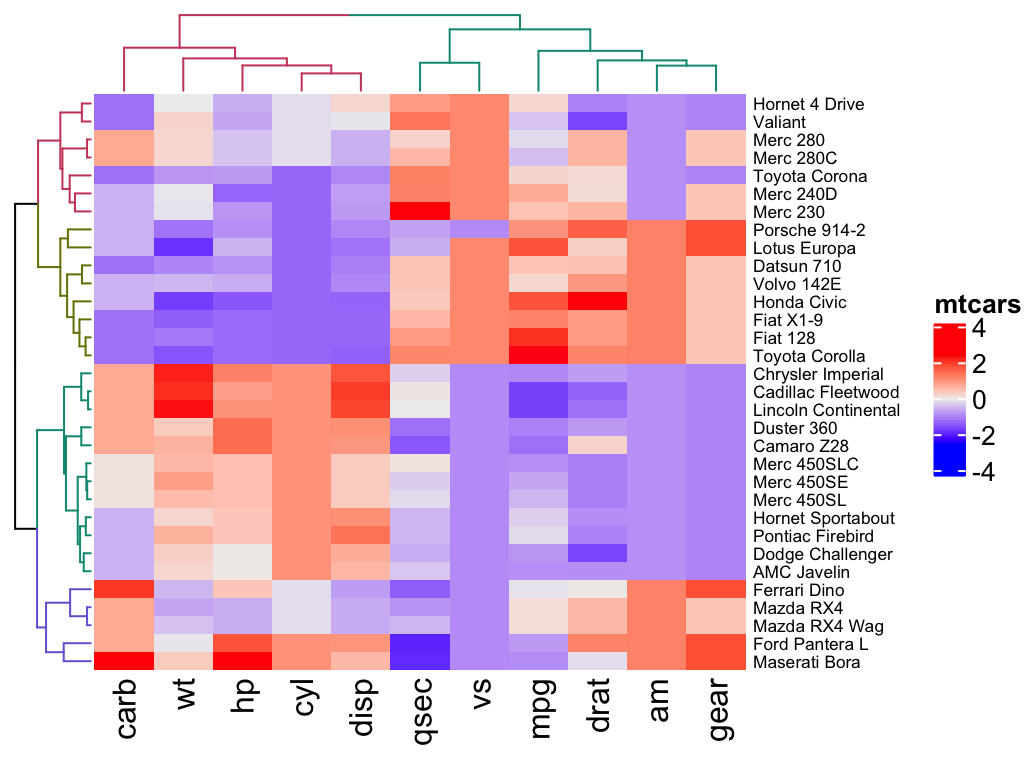

Data visualization through heatmap

It is possible to find a corresponding computational branch for every major field in physics, for example:

- **Computational electrodynamics** is the process of modeling the interaction of electromagnetic fields with physical objects and the environment.

- **Computational solid state physics** is a very important division of computational physics dealing directly with material science.

- **Computational statistical mechanics** is a field related to computational condensed matter which deals with the simulation of models and theories that are difficult to solve otherwise.

- **Computational statistical physics** makes heavy use of Monte Carlo-like methods.

- **Computational astrophysics** is the application of these techniques and methods to astrophysical problems and phenomena.

## Git Version Control

## Software Environment

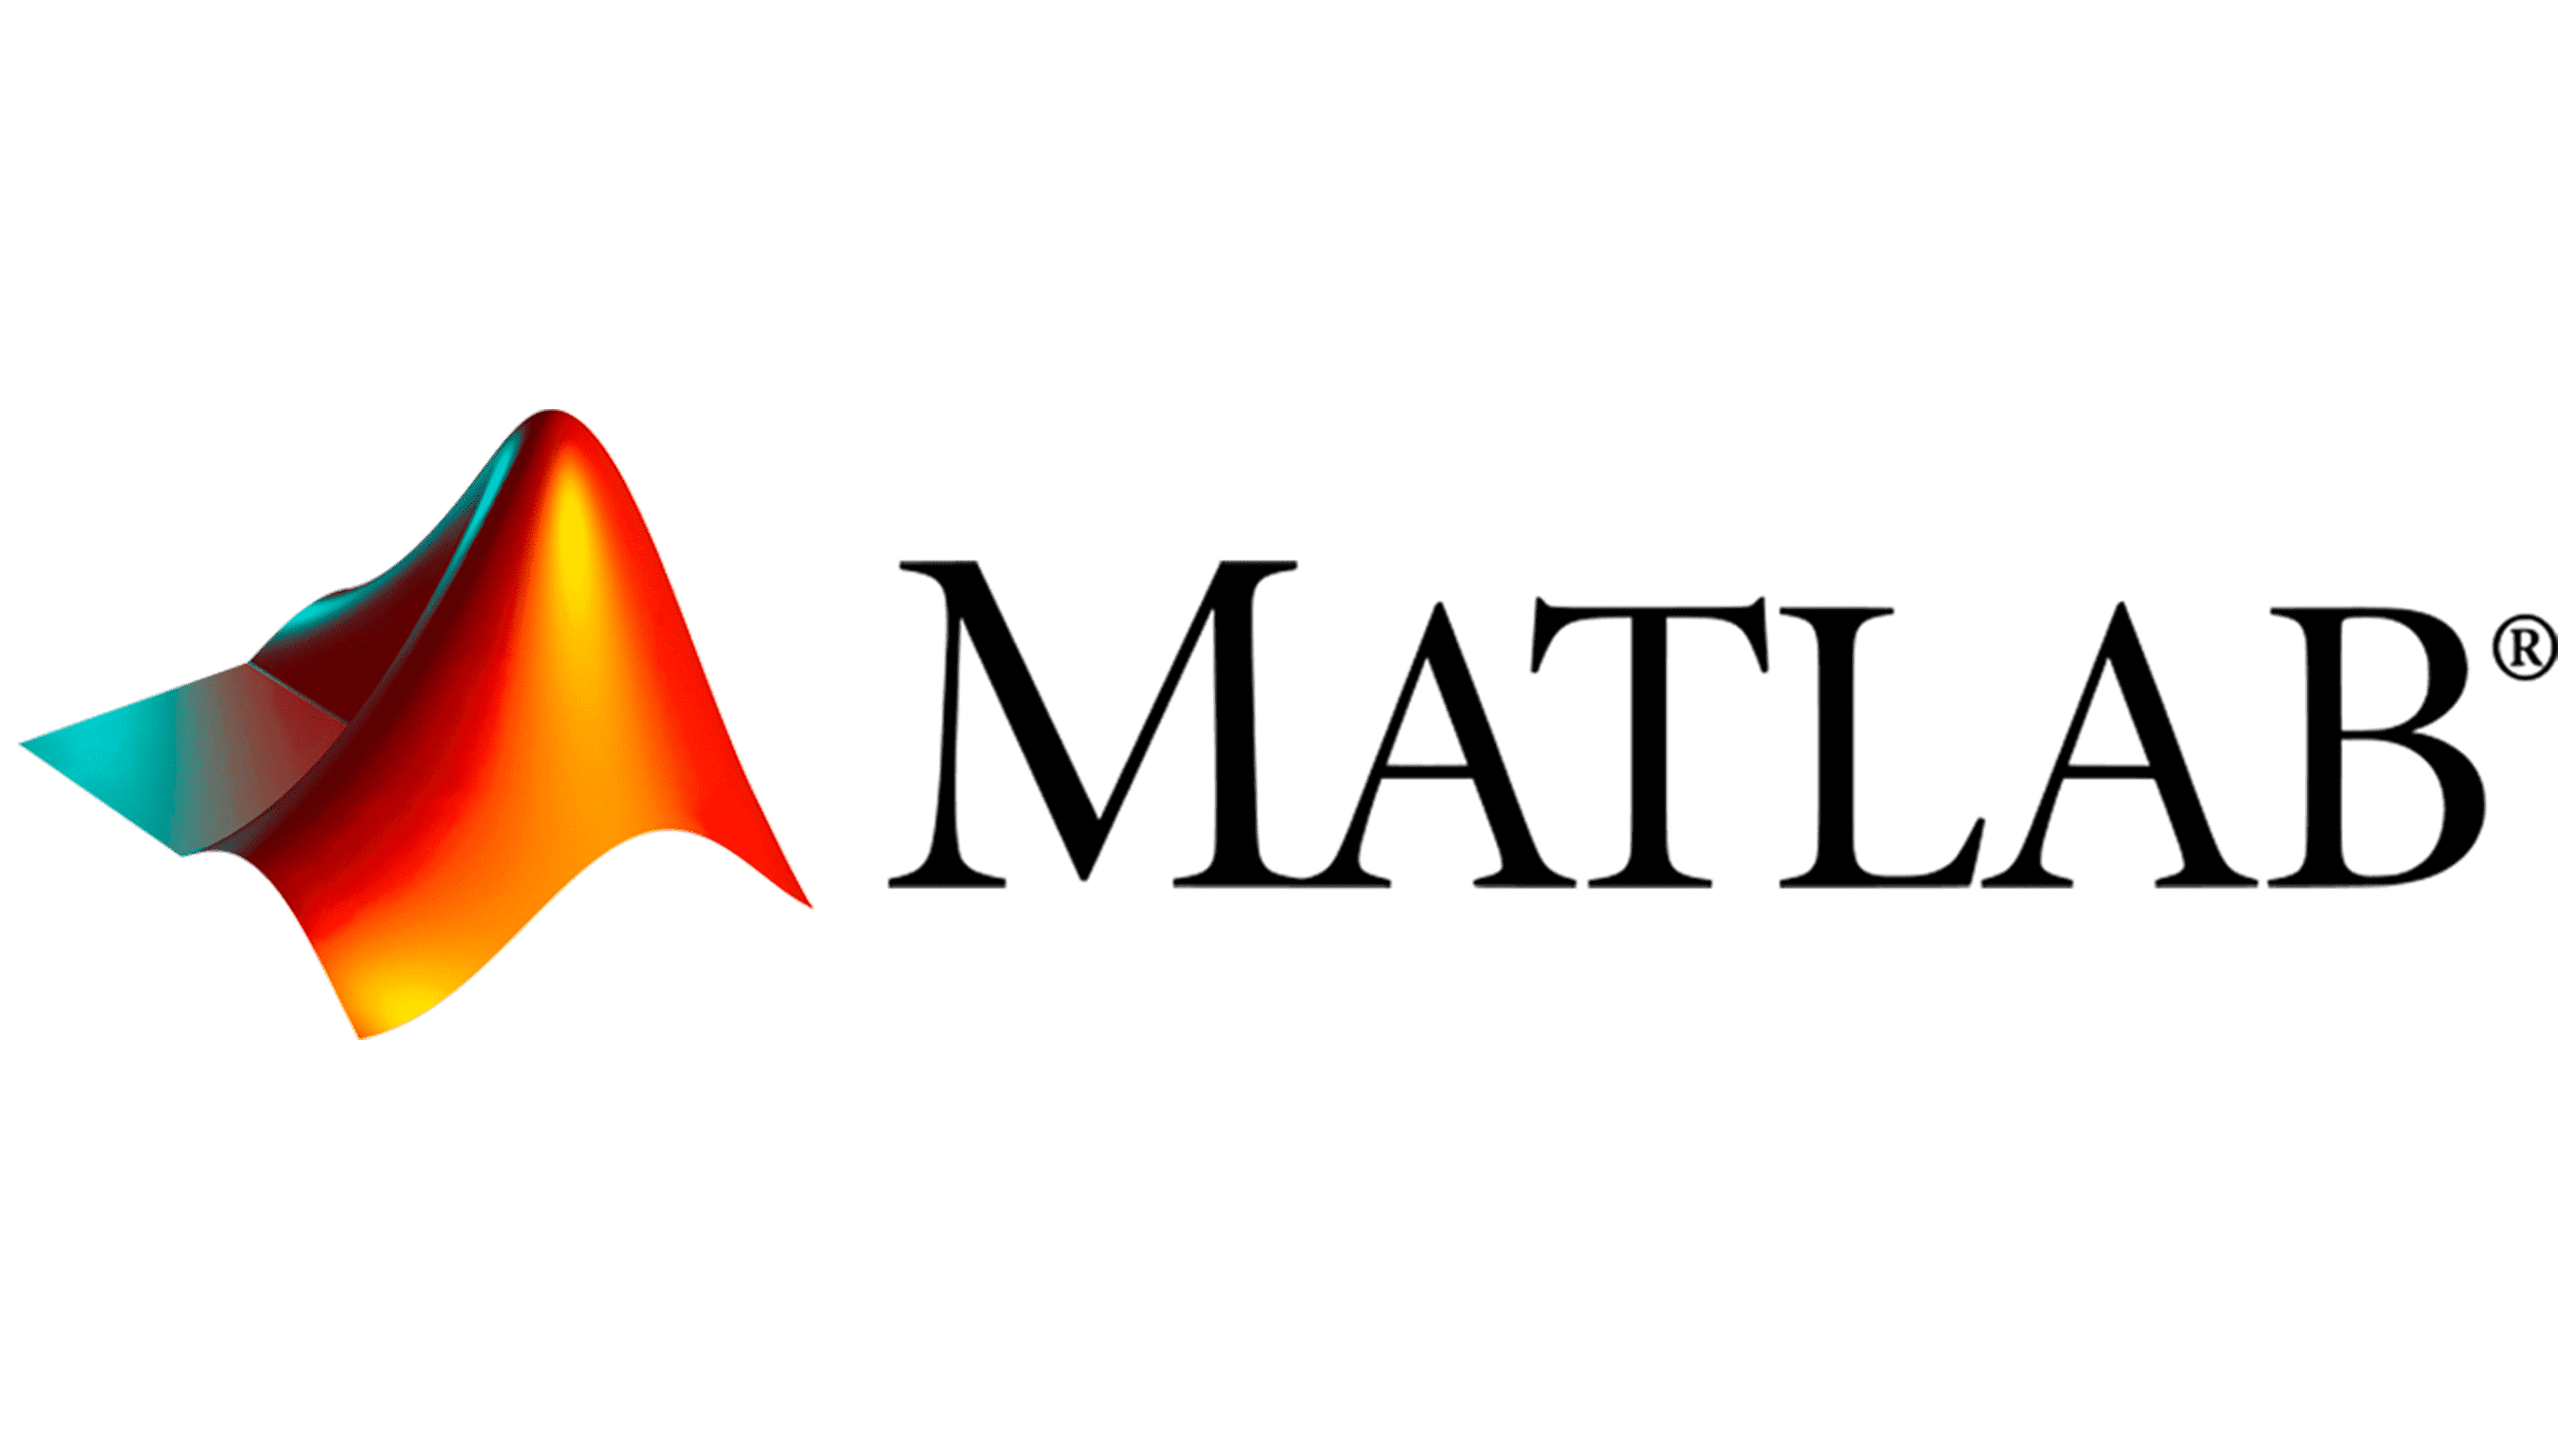

**MATLAB** is a powerful technical computing system for handling scientific and engineering calculations. The name MATLAB stands for **Matrix Laboratory**, because the system was designed to make matrix computations particularly easy. The MATLAB user interface consists of several components such as the Command Window, the Workspace browser, the Editor window, and the Help browser, collectively known as integrated development environment (IDE). The IDE allows you to interact with MATLAB by typing commands, editing and debugging code, managing files and variables, accessing documentation and online resources.

### Command Window

To demonstrate running scripts as commands, enter the following in Command Window: 

Balance = 1000;
Rate = 0.09;
Interest = Rate * Balance;
Balance = Balance + Interest;
disp('New balance:' );
disp(Balance);

When you press Enter to run it, observe the output in the Command Window. Obviously you need to save the program if you want to use it again later. To write a script to be later saved, use Editor.

### Editor

To get started, type the following script into the Editor : 

Matrix = magic(3)   % Generate a 3 x 3 magic square
InverseMatrix = inv(Matrix);
PredictedIdentityMatrix = Matrix * InverseMatrix;
IdentityMatrix = eye(3);
PredictionError = PredictedIdentityMatrix - IdentityMatrix;
SmallestInterval = eps;
for m = 1 : 3
    for n = 1 : 3
        if PredictionError(m, n) < SmallestInterval
            PredictedIdentityMatrix(m, n) = IdentityMatrix(m, n);
        end
    end
end
IdentityMatrix
PredictedIdentityMatrix

Then click on the Run button just under the tab named Editor or Live Editor. The first time the script is executed you are asked to name the file. In this example use `MatrixMultiplication.m` as the name. If all lines are typed correctly, except those that are preceded by the `%` symbol (because those are comments to describe the code and are ignored when script is executed), outputs will be shown in Command Window. 

You can also run the script by calling the file name without the "`.m"` extension in Command Window as follows:

MatrixMultiplication

### Workspace

Define some commonly used constant:

GravityAcceleration = 9.81;
AvogadroConst = 6.023e23; 
BaseLn = exp(1);
Bar2KiloPascal = 101.325;
Value = pi / 4;

Enter the command `who` and `whos` to see the list of variables in the Workspace:

who
whos

The command `clearvars` removes all variables from the workspace:

clearvars

### Documentation

MATLAB provides self-contained documentation for all features and functions that it offers. The `help` and `doc` functions in MATLAB are both used to access the documentation of MATLAB functions and commands:

help magic
doc eye

The main difference between the functions is that `help` displays the information in the Command Window, while `doc` opens a separate window with more details and examples

## Variables

A variable is created simply by assigning a value to it at the command line in a program – for example:

Number = 98

All variables are considered arrays, whether they are single-valued (scalars) or multi-valued (vectors or matrices). In other words, a scalar is a 1-by-1 array – an array with a single row and a single column.

### Variable Naming

A variable name must comply with the following rules:

- It may consist only of the letters a – z, the digits 0 – 9, and the underscore. 

- It must start with a letter.

- It is case-sensitive

Some practices of variable naming are recommended:

- Use **meaningful names** for variables. Variable name must define the exact explanation of its content. For physical quantities, embed the unit in the name, if possible. For examples, use `BoxWidth`, `RoomTemperature` and `WattUsage` instead of y, `RT` and `Pwr.`

- **Single-letter lowercase** variables like `i` or `j` are usually used for **loop counters**; however, their usage are acceptable for well-recognized **mathematical unknowns** in an equation. Names that have one to four words are acceptable for other types of variables.

- Obey programming language standards and **do not use lowercase/uppercase characters inconsistently**. Many MATLAB programmers use `UpperCamelCase` for variable names because it is arguably the easiest to read. To distinguish variables from functions, use `camelCase` for function names.

- Mimic parts of speech of the English language. Use verbs for functions (e.g., `extractData`, `plotData`, `showDataUnit`), nouns for common variables (e.g., `ExtractedData`, `PlottedData`, `DataUnit)` and true/false questions for logical variables (e.g., `IsDataExtracted`, `CanPlotData`, `HasDataUnit)`.

### Data Import/Export

Data are saved in disk files in one of two formats: text or binary. In text format, data values are ASCII codes, and can be viewed in any text editor. In binary format, data values are not ASCII codes and cannot be viewed in a text editor. You may wish to import data to be plotted or operated on mathematically, and export data for future use. If you want to save data between MATLAB sessions, use `save` and `load` functions.

To export (save) the following array:

Array = [1, 2, 3; 4, 5, 6]

in delimited ASCII format in the file `MyData.txt` use the command:

save MyData.txt Array -ascii

The load command is the reverse of save, but has a curious twist. If the array `A` has been saved in `MyData.txt` as above the command 

load MyData.txt

creates a variable in the workspace with the same name as the file, minus the extension, i.e., `MyData`. 

If you don’t want the filename as the variable name use the functional form of the command, e.g.:

Numbers = load('MyData.txt')

If the variables `x`, `y` and `z` exist in the workspace, the command:

[x, y, z] = deal(2, [1, 2, 3], [4; 5; 6])
save MyVariables x y z

saves the variables `x, y` and `z` in the file `MyVariables.mat` in MATLAB proprietary binary format, i.e., such a MAT-file can only be used by MATLAB.

The command: 

load MyVariables

loads all the variables from `MyVariables.mat` into the workspace; see help for all the `load` options.

## Computer Precision

Computer precision is a measure of how accurately a numerical value can be represented in a computer memory. It depends on the number of bits used to store the value and the format of the value. Floating-point format is one of the common formats for representing fractional or very large values by using a "floating point". It is called floating point because the decimal point can "float" to any position necessary to represent a number. For example, $0\ldotp 00123$ can be written as $1\ldotp 23\times {10}^{-3}$ where the decimal point has moved three places to the left.

**Double** and **single floating-point **are two types of floating-point formats that differ in their precision and range. Double floating-point uses 64 bits to store a value, while single floating-point uses 32 bits. This means that double floating-point can represent more digits and larger values than single floating-point, but it also takes more memory space and computation time. 

A floating-point number consists of three parts: a sign bit, an exponent part, and a fraction part. For a double floating-point number, the sign bit (1 bit) indicates whether the number is positive or negative. The exponent part  (7 bits for numbers and 1 bit for its sign) determines the magnitude or scale of the number. The fraction part (52 bits) specifies the digits after the decimal point.

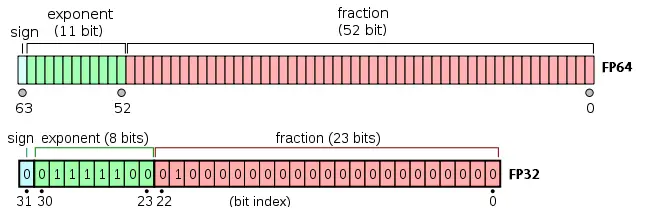

The largest positive value that can be represented by double floating-point is about $\left(2-2^{-52} \right)\times 2^{1023}$, while for single floating-point it is about $\left(2-2^{-23} \right)\times 2^{127}$. Check using `realmax` function:

realmax('double')
realmax('single')

## Operators, Expressions and Statements

Numbers can be represented in the usual decimal form (fixed point) with an optional decimal point:

[1.2345 -123 .0001 1.2345e9]

The default numeric data type is double precision; all MATLAB computations are in `double`. MATLAB also supports signed and unsigned integer types and single-precision floating-point, by means of functions such as `int8`, `uint8`, `single` and so on.

The arithmetic operations on two scalar constants or variables are shown below:

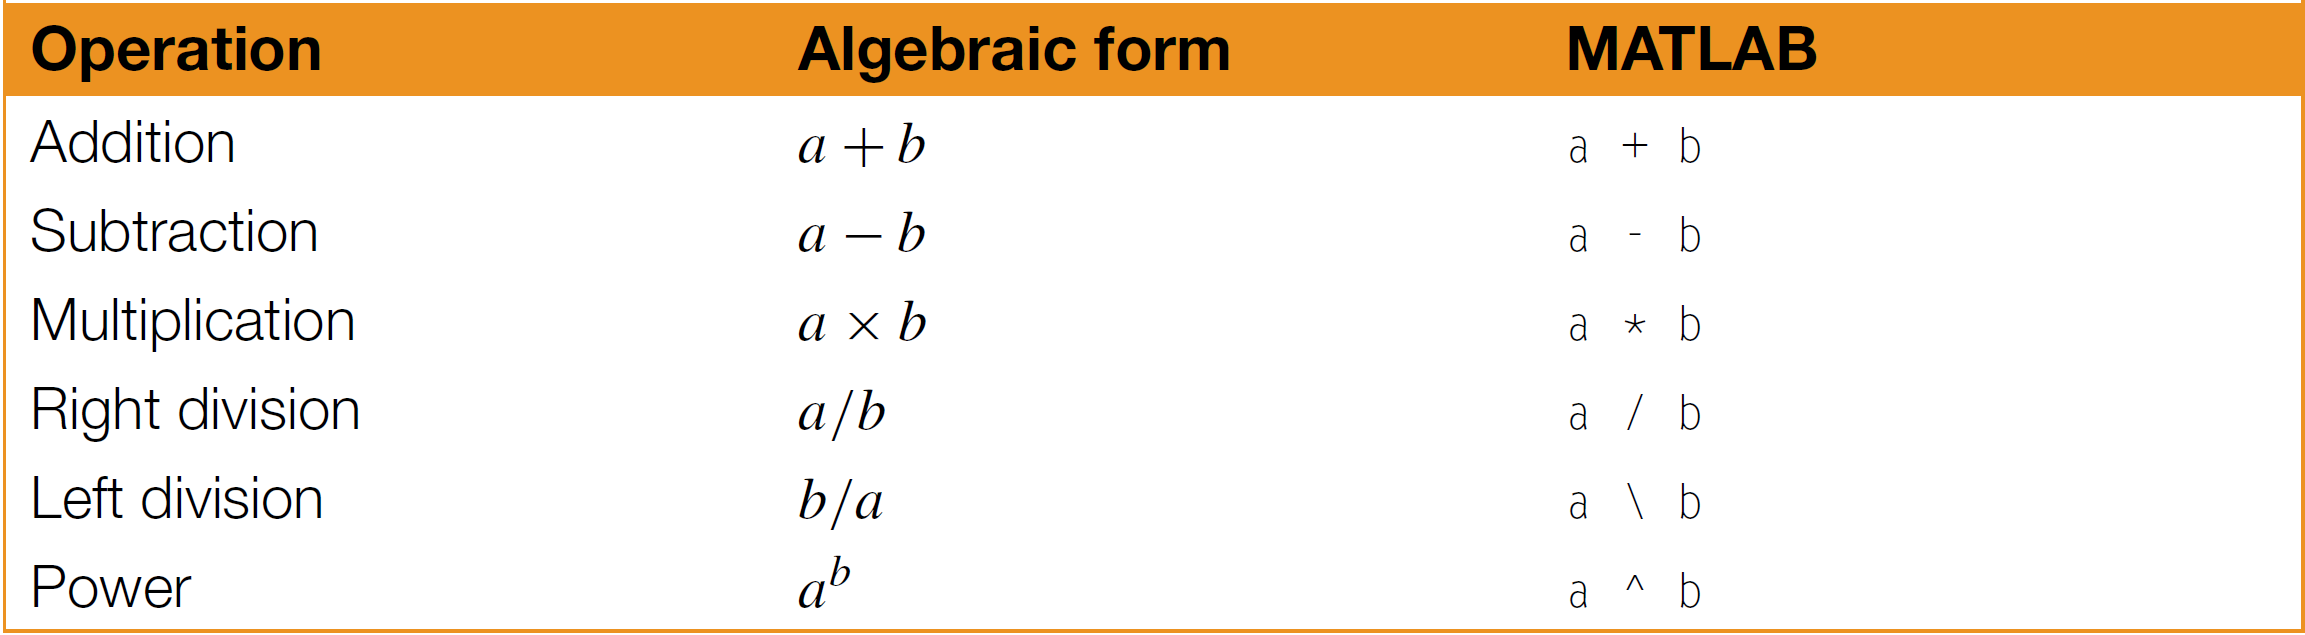

The precedence rules for the operators in are shown below:

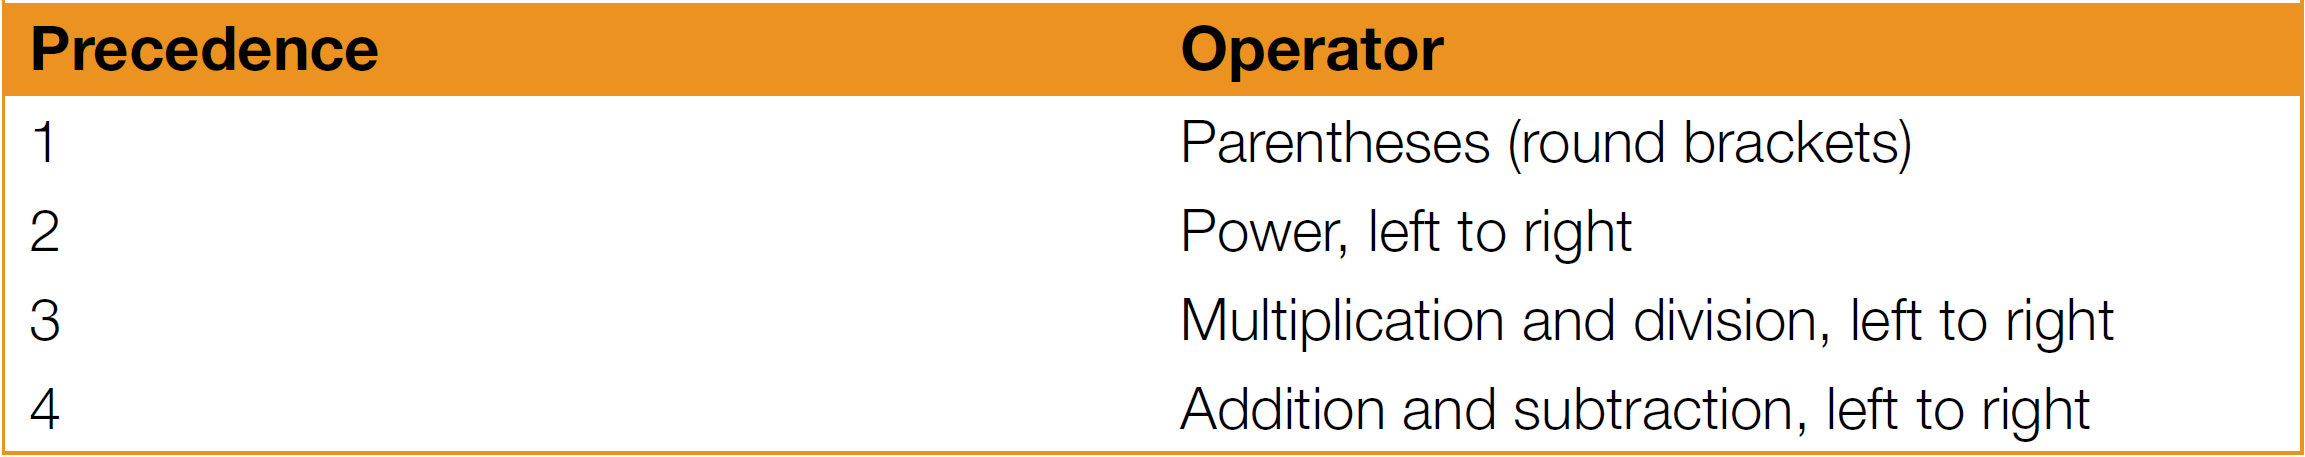

MATLAB has four additional arithmetic operators, as shown below that work on corresponding elements of arrays with equal dimensions. They are sometimes called array or element-by-element operations because they are performed element by element:

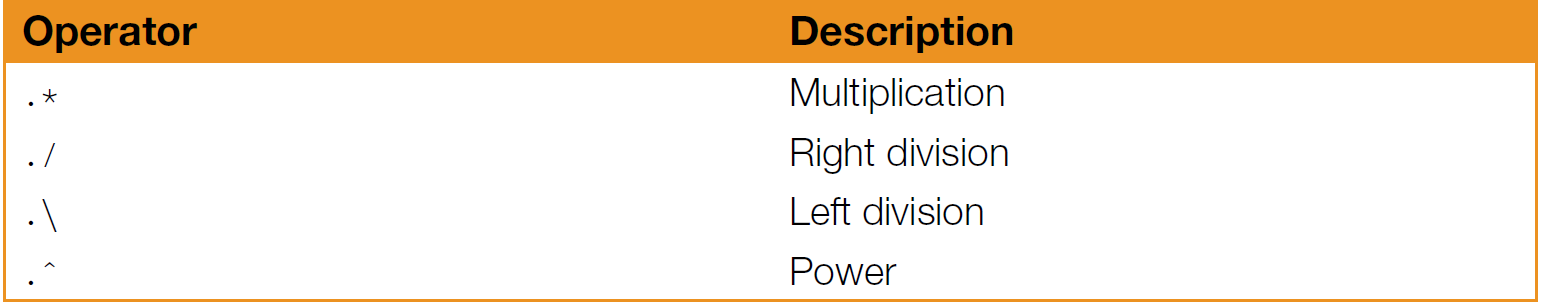

For example:

VecA = [2 4 5];
VecB = [6 2 2];
VecA .* VecB

Compare the output with:

[VecA(1)*VecB(1) VecA(2)*VecB(2) VecA(3)*VecB(3)]

An expression is a formula consisting of variables, numbers, operators, and function names.

2 * pi

MATLAB statements are frequently of the form `variable = expression.`

With array operations, you can easily evaluate a formula repeatedly for a large set of data; this is called formula vectorization:

Numbers = [750, 1000, 3000, 5000, 11999];
Value = 0.09;
Integer = 10;
TotalValue = Numbers * (1 + Value) ^ Integer;
disp([Numbers', TotalValue'])

MATLAB supports two types of syntax for calling functions: command syntax and function syntax. Command syntax passes inputs as character vectors and cannot pass variable values. Function syntax passes inputs as arguments enclosed in parentheses and can pass variable values. For example:

save MyData.txt Array -ascii % Command syntax
save('MyData.txt', 'Array', '-ascii') % Function syntax

Command syntax is useful for interactive work when you want to avoid typing quotes and parentheses, but function syntax is more flexible and robust.

## Mathematical Functions

Interesting problems in science and engineering are likely to involve special mathematical functions like sines, cosines, logarithms, etc. MATLAB comes with a large collection of such functions.

x = -pi
y = 2*pi / 3

abs(x)      % Absolute value of x
acos(x)     % Arc cosine (inverse cosine) of x between 0 and π
acosh(x)    % Inverse hyperbolic cosine of x, i.e., ln(x + √x2 − 1)
asin(x)     % Arc sine (inverse sine) of x between −π/2 and π/2
asinh(x)    % Inverse hyperbolic sine of x, i.e., ln(x + √x2 + 1)
atan(x)     % Arc tangent of x between −π/2 and π/2
atan2(y, x) % Arc tangent of y/x between −π and π
atanh(x)    % Inverse hyperbolic tangent of x
ceil(x)     % Smallest integer which exceeds x, i.e., rounds up to nearest integer, e.g., ceil(-3.9) returns -3, ceil(3.9) returns 4
cos(x)      % Cosine of x
cosh(x)     % Hyperbolic cosine of x
cot(x)      % Cotangent of x
csc(x)      % Cosecant of x
cumsum(x)   % Cumulative sum of the elements of x, e.g., cumsum(1:4) returns [1 3 6 10]
datetime    % Current date and time in a string in HH:mm:ss dd-MMM-yyyy format
exp(x)      % Value of the exponential function e^x
fix(x)      % Rounds to the nearest integer towards zero, e.g., fix(-3.9) returns -3, e.g., fix(3.9) returns 3
floor(x)    % Largest integer not exceeding x, i.e., rounds down to nearest integer, e.g. floor(-3.9) % Returns -4, floor(3.9) returns 3
length(x)   % Number of elements of vector x
log(x)      % Natural logarithm of x
log10(x)    % Base 10 logarithm of x
max(x)      % Maximum element of vector x
mean(x)     % Mean value of elements of vector x
min(x)      % Minimum element of vector x
pow2(x)     % 2^x
prod(x)     % Product of the elements of x
rand        % Pseudo-random number in the interval (0, 1)
realmax     % Largest positive floating point number on your computer
realmin     % Smallest positive floating point number on your computer
rem(x, y)   % Remainder when x is divided by y, e.g., rem(19, 5) returns 4 (5 goes 3 times into 19, remainder 4)

### Physics Pinpoint 🔎: Uniformly Distributed Load

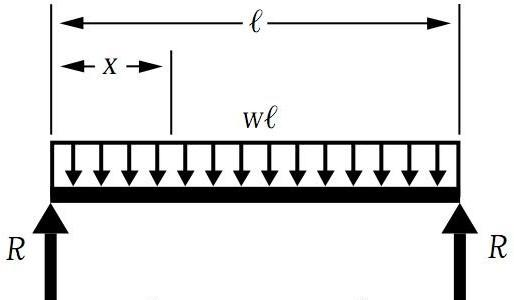

A uniform beam is freely hinged at its ends $x=0$ and $x=L$, so that the ends are at the same level. It carries a uniformly distributed load of $W$ per unit length, and there is a tension $T$ along the $x$-axis. The deflection $y$ of the beam a distance $x$ from one end is given by:


$$y=\frac{\textrm{WEI}}{T^2 }\left\lbrack \frac{\cosh \left(a\left(L/2-x\right)\right)}{\cosh \left(\textrm{aL}/2\right)}-1\right\rbrack +\frac{\textrm{Wx}\left(L-x\right)}{2T}$$


where $a^2 =\frac{T}{\textrm{EI}}$, $E$ being the Young’s modulus of the beam, and $I$ is the moment of inertia of a cross-section of the beam. The beam is 10 m long, the tension is 1 000 N, the load 100 N/m, and $\textrm{EI}={10}^4$. The script to compute and plot a graph of the deflection $y$ against $x$ is:

EI = 10^4;
T = 1000;
W = 100;
a = sqrt(T/EI);
L0 = 0;
L = 10;
x = L0 : 0.1 : L;
y = (W*EI/T^2)*(cosh(a*(L./2-x)) / cosh((a*L)./2)) + (W*x.*(L-x))/(2*T);
plot(x, y)
set(gca, XLim = [0, 10], YLim = [0, 10], YDir = 'reverse');
title('A uniformly distributed load on a beam');
xlabel('Horizontal distance, x (m)');
ylabel('Vertical deflection, y (m)');